close all
clear 
g = 9.7949;
L = 97.95e-3; % mm
k1 = 24.8e-3 * g / L; % N/m
k2 = 66.6e-3 * g / L;
k = k1 + k2

k = 9.1399

mk = 28e-3; % kg
m = 214.8e-3;
Na = 224;
la = 122.4e-3 ;
Nb = 236;
lb = 124.6e-3; %mm
beta = 1/3;
omega0_theor= sqrt(k / (m + mk * beta))

omega0_theor = 6.3858

path = "C:/Users/Evgeny/Downloads/rre/"

path = "C:/Users/Evgeny/Downloads/rre/"

A = [];
Phi = [];
Omega = [];
for i=1 : 10
    filename = path + int2str(i)+".txt";
    [t, countA, countB] = importfile(filename);
    xa = countA / Na * la;
    xb = countB / Nb * lb;
    xa = xa - mean(xa);
    xb = xb - mean(xb);
    [peaks, locs] = findpeaks(xa);
    T = mean(diff(t(locs)));
    omega = 2 * pi / T;
    [amp, phase] = response(xa, xb);
    A(end+1) =  amp;
    Phi(end+1) = phase;
    Omega(end+1) = omega ;
end

figure()
%plot(Omega, A, 'x')
[fitresult, gof] = FitAmplitude(Omega, A, k1, k)

expression = '0.271335 /sqrt((1-(om/om0)^2)^2 + (om/om0/Q)^2)'

fitresult =      General model:
     fitresult(om) = 0.271335 /sqrt((1-(om/om0)^2)^2 + (om/om0/Q)^2)
     Coefficients (with 95% confidence bounds):
       Q =      -30.67  (-32.21, -29.13)
       om0 =       6.453  (6.449, 6.457)

gof = struct with fields:
           sse: 0.0033
       rsquare: 0.9999
           dfe: 8
    adjrsquare: 0.9998
          rmse: 0.0202


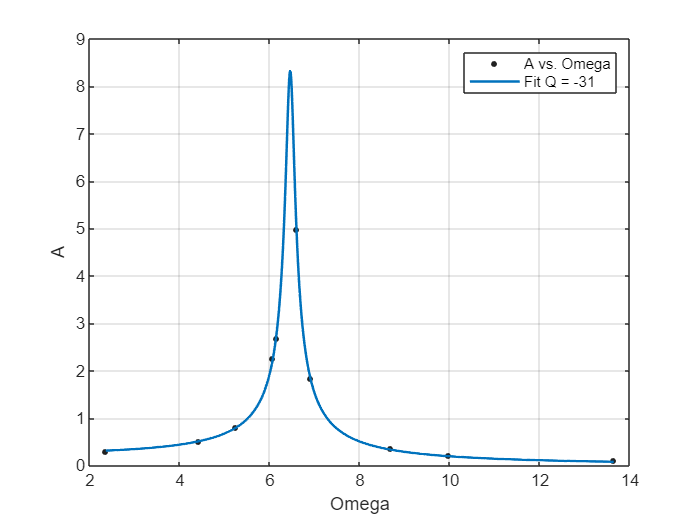

% Plot fit with data.
figure( 'Name', 'Amplitude fit' );
h = plot( fitresult, Omega, A);
legend( h, 'A vs. Omega', sprintf('Fit Q = %.0f', fitresult.Q));
% Label axes
xlabel( 'Omega', 'Interpreter', 'none' );
ylabel( 'A', 'Interpreter', 'none' );
grid on




figure()
%plot(Omega, Phi, 'x')
[fitresult, gof] = FitPhase(Omega, Phi)

fitresult =      General model:
     fitresult(om) = cos( mod( atan(om * om0 / Q / (om0^2 - om^2)), pi))
     Coefficients (with 95% confidence bounds):
       Q =       26.45  (18.8, 34.11)
       om0 =       6.371  (6.302, 6.439)

gof = struct with fields:
           sse: 0.0115
       rsquare: 0.9987
           dfe: 8
    adjrsquare: 0.9986
          rmse: 0.0380


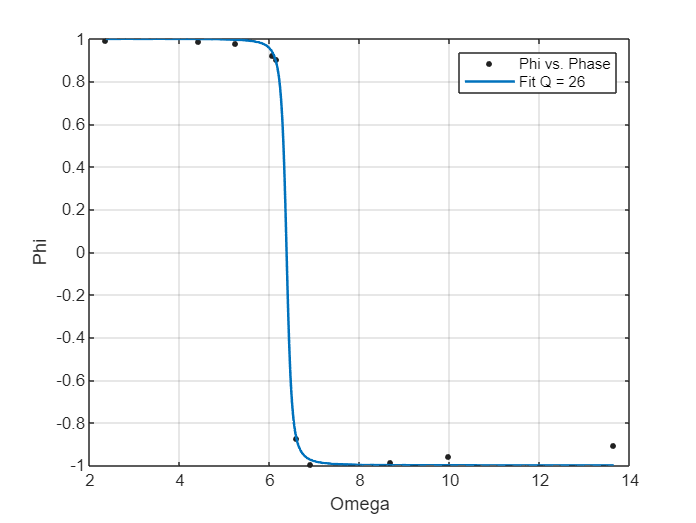

% Plot fit with data.
figure( 'Name', 'Phase fit' );
h = plot( fitresult, Omega, Phi);
legend( h, 'Phi vs. Phase', sprintf('Fit Q = %.0f', fitresult.Q));
% Label axes
xlabel( 'Omega', 'Interpreter', 'none' );
ylabel( 'Phi', 'Interpreter', 'none' );
grid on

function [t, countA, countB] = importfile(filename, dataLines)
%IMPORTFILE Import data from a text file
%  [T, COUNTA, COUNTB] = IMPORTFILE(FILENAME) reads data from text file
%  FILENAME for the default selection.  Returns the data as column
%  vectors.
%
%  [T, COUNTA, COUNTB] = IMPORTFILE(FILE, DATALINES) reads data for the
%  specified row interval(s) of text file FILENAME. Specify DATALINES as
%  a positive scalar integer or a N-by-2 array of positive scalar
%  integers for dis-contiguous row intervals.
%
%  Example:
%  [t, countA, countB] = importfile("D:\resonanse.txt", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 07-Jan-2025 00:34:01

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "t", "countA", "countB", "Var5", "Var6"];
opts.SelectedVariableNames = ["t", "countA", "countB"];
opts.VariableTypes = ["string", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var5", "Var6"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var5", "Var6"], "EmptyFieldRule", "auto");

% Import the data
tbl = readtable(filename, opts);

%% Convert to output type
t = tbl.t;
countA = tbl.countA;
countB = tbl.countB;
end

function [amplitude,cosphi] = response(xa, xb)

a = sqrt(dot(xa, xa));
b = sqrt(dot(xb, xb));
ab = dot(xa, xb);
amplitude = b / a;
cosphi = ab / a/ b;
end

function [fitresult, gof] = FitAmplitude(Omega, A, k1, k)
%CREATEFIT(OMEGA,A)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : Omega
%      Y Output: A
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 07-Jan-2025 02:21:49


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( Omega, A );

expression = sprintf('%f /sqrt((1-(om/om0)^2)^2 + (om/om0/Q)^2)', k1/k)
% Set up fittype and options.
ft = fittype( expression, 'independent', 'om', 'dependent', 'A' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [6.8 25];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

end


function [fitresult, gof] = FitPhase(Omega, Phi)


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( Omega, Phi );

expression = 'cos( mod( atan(om * om0 / Q / (om0^2 - om^2)), pi)) ';
% Set up fittype and options.
ft = fittype( expression, 'independent', 'om', 'dependent', 'A' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [6.8 25];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

end


$A = \frac{k_1}{k_1+k_2} \left[ \left(1-\frac{\omega}{\omega_0}^2\right)^2  + \left(\frac{1}{Q}\frac{\omega}{\omega_0}\right)^2 \right]^{-1/2}, \\

\cos \psi = \cos\, \arctan \frac{1}{Q} \frac{\omega \, \omega_0}{\omega_0^2 - \omega^2}$, 